# **ISB-workshop 2021**

This script formulates and solves a trajectory optimization problem underlying a predictive simulation of walking with a planar five-link biped model. A direct collocation method with a backward Euler integration scheme is employed to formulate a nonlinear programming problem (NLP) from the continuous optimization problem. 

The formulation is deeply inspired from the five-link biped example described in: "Kelly, An Introduction to Trajectory Optimization: How to Do Your Own Direct Collocation (2017), SIAM REVIEW. DOI. 10.1137/16M1062569".

Author: Tom Van Wouwe 

Contributors: Antoine Falisse and Gil Serrancolí

### **Import CasADi**

import casadi.*

### Selection of walking pattern and weight of cost function terms.

Options:

- nominal

- no_stance_ankle_torque

- no_stance_knee_torque

- no_hip_torques

- only_stance_ankle_torque

- only_knee_torques

- only_hip_torques

- crouch_gait

- swing_foot_circles_around_stance_foot

- on_the_moon

- on_mars

selected_gait = 'nominal';

The cost function minimizes the sum of the squared joint torques. The contribution of each joint is weighted with a separate weight factor as follows: J = w1*T1^2 + w2*T2^2 + w3*T3^2 + w4*T4^2 + w5*T5^2.

We expose those weight factors here so that you can easily change them, and see what is the impact on the predicted walking pattern.

w1 = 1; % stance ankle
w2 = 1; % stance knee
w3 = 1; % stance hip
w4 = 1; % swing hip
w5 = 1; % swing knee

### Model: physical parameters and dynamics.

The model consists of a torso connected to two legs, each of which has an upper and a lower link. The stance leg is supporting the weight of the model, while the swing leg is free to move above the ground. Each link is modeled as a rigid body, with both mass and rotational inertia. Links are connected to each other with ideal torque motors across frictionless revolute joints. In contrast with the model from the paper, the stance ankle is not passive (i.e., the torque is not null). (TODO: confirm)

Physical parameters for the five-link biped model.

Table 4 from appendix E.2, p897 of Kelly 2017.

-------------------------------------------------------------------------

Symbol    Value         Name

-------------------------------------------------------------------------

m1, m5    3.2 kg        mass of the tibia (lower leg)

m2, m4    6.8 kg        mass of the femur (upper leg)

m3           20 kg         mass of the torso

-------------------------------------------------------------------------

I1, I5    0.93 kg-m2    rotational inertia of tibia about center of mass

I2, I4    1.08 kg-m2    rotational inertia of femur about center of mass

I3         2.22 kg-m2    rotational inertia of torso about center of mass

-------------------------------------------------------------------------

l1, l5    0.4 m         length of tibia

l2, l4    0.4 m         length of femur

l3        0.625 m       length of torso

-------------------------------------------------------------------------

d1, d5    0.128 m       distance from tibia center of mass to knee

d2, d4    0.163 m       distance from femur center of mass to hip

d3          0.2 m         distance from torso center of mass to hip

-------------------------------------------------------------------------

Mass of the segments.

m1 = 3.2; m5 = 3.2;
m2 = 6.8; m4 = 6.8;
m3 = 20;

Rotational inertia of the segments.

I1 = 0.93; I5 = 0.93;
I2 = 1.08; I4 = 1.08;
I3 = 2.22;

Length of the segments.

l1 = 0.4; l5 = 0.4;
l2 = 0.4; l4 = 0.4;
l3 = 0.625;

Distance from segment center of mass to parent joint.

d1 = 0.128; d5 = 0.128;
d2 = 0.163; d4 = 0.163;
d3 = 0.2;

Gravity

if strcmp(selected_gait, 'on_the_moon')
    g = 1.62;
elseif strcmp(selected_gait, 'on_mars')
    g = 3.72;
else
    g = 9.81;
end

(TODO name: are those really named dynamic constraints?)

For the sake of simplicty, we generated the equations of motion of the model for you (see how we proceeded in generateSymbolicFunctions.m). 

Here, we create a CasADi function that returns the dynamic constraint errors based on the model states (q, dq) and controls (ddq, T). This function is initialized based on the physical parameters of the model, such that if you change those parameters, the equations of motion are updated. During the actual optimization, we will impose the dynamic contraint errors to be null. Note that you can change the physical parameters of the model, but not for instance add a segment. This would make current dynamics invalid.

f_getDynamicConstraintErrors:

Inputs:

  - states: joint positions q (5x1)

  - states: joint velocities dq (5x1)

  - controls: joint accelerations ddq (5x1)

  - controls: joint torques T (5x1)

Outputs:

  - dynamic contraint errors (5x1)

f_getDynamicConstraintErrors = getDynamicConstraintErrors(...
    m1, m2, m3, m4, m5, ...
    I1, I2, I3, I4, I5, ...
    d1, d2, d3, d4, d5, ...
    l1, l2, l4, l5, ...
    g);

### Trajectory optimization problem formulation.

Stride time and length, and mesh size.

Those are parameters you can play with. If you use a lower mesh size, this should increase the accuracy of your simulation, but likely at the cost of higher computational time. In practice, if your solution changes when lowering the mesh size, it suggests that your current mesh size is not low enough. It is advised to do such type of convergence analysis to make sure you don't over-interpret the results.

strideTime = 0.8;           % Stride time (s).
strideLength = 0.5;         % Stride length (m).
dt = 0.01;                  % Mesh size (s).

N = strideTime/dt;          % Number of mesh intervals.
time = 0:dt:strideTime;     % Discretized time vector.

The NLP is formulated using Opti Stack, which is a collection of CasADi helper classes that provides a close correspondence between mathematical NLP notation and computer code.

More info here: https://web.casadi.org/docs/#document-opti

Create opti instance.

opti = casadi.Opti(); 

#### Create design variables

States.

Joint positions.

q1 = opti.variable(1,N+1);   q2 = opti.variable(1,N+1);   
q3 = opti.variable(1,N+1);   q4 = opti.variable(1,N+1);   
q5 = opti.variable(1,N+1);

Joint velocities.

dq1 = opti.variable(1,N+1);  dq2 = opti.variable(1,N+1);  
dq3 = opti.variable(1,N+1);  dq4 = opti.variable(1,N+1);  
dq5 = opti.variable(1,N+1);

Controls.

Joint accelerations.

ddq1 = opti.variable(1,N);   ddq2 = opti.variable(1,N);   
ddq3 = opti.variable(1,N);   ddq4 = opti.variable(1,N);   
ddq5 = opti.variable(1,N);

Joint torques.

T1 = opti.variable(1,N);     T2 = opti.variable(1,N);     
T3 = opti.variable(1,N);     T4 = opti.variable(1,N);     
T5 = opti.variable(1,N);

#### Bounds

Set bounds on joint positions (if not otherwise specified, design variables will be bounded between +/- Inf).

opti.subject_to(-pi/2 <= q1 <= pi/2);
opti.subject_to(-pi/2 <= q2 <= pi/2);
opti.subject_to(-pi/3 <= q3 <= pi/3);
opti.subject_to(-pi/2 <= q4 <= pi/2);
opti.subject_to(-pi/2 <= q5 <= pi/2);

Set physiological joint limits.

opti.subject_to(-pi <= q1 - q2 <= 0); % Knee joint limit (no hyperflexion).
opti.subject_to(-pi <= q5 - q4 <= 0); % Knee joint limit (no hyperflexion).

#### Initial guess

Set naive initial guess for the joint positions.

(linearly spaced vector between lower and upper bounds).

When no initial guess is provided, numerical zero is assumed.

q1_init = -pi/8;    q1_final = -pi/6;   
q2_init = pi/6;     q2_final = -pi/8;
q3_init = -pi/6;    q3_final = 0;
q4_init = -pi/8;    q4_final = pi/6;
q5_init = -pi/6;    q5_final = -pi/8;
q1guess = linspace(q1_init, q1_final, N+1);
q2guess = linspace(q2_init, q2_final, N+1);
q3guess = linspace(q3_init, q3_final, N+1);
q4guess = linspace(q4_init, q4_final, N+1);
q5guess = linspace(q5_init, q5_final, N+1);
opti.set_initial(q1, q1guess);
opti.set_initial(q2, q2guess);
opti.set_initial(q3, q3guess);
opti.set_initial(q4, q4guess);
opti.set_initial(q5, q5guess);

Initialize the cost function (J).

J = 0;

Loop over mesh points.

for k=1:N
    % States at mesh point k.
    % Joint positions.
    q1k = q1(:,k);     q2k = q2(:,k);     q3k = q3(:,k);
    q4k = q4(:,k);     q5k = q5(:,k);
    % Joint velocities.
    dq1k = dq1(:,k);   dq2k = dq2(:,k);   dq3k = dq3(:,k);
    dq4k = dq4(:,k);   dq5k = dq5(:,k);
    
    % Controls at mesh point k.
    % Joint accelerations.
    ddq1k = ddq1(:,k); ddq2k = ddq2(:,k); ddq3k = ddq3(:,k); 
    ddq4k = ddq4(:,k); ddq5k = ddq5(:,k);
    % Joint torques.
    T1k = T1(:,k);     T2k = T2(:,k);     T3k = T3(:,k);     
    T4k = T4(:,k);     T5k = T5(:,k);
    
    % States at mesh point k+1.
    % Joint positions.
    q1k_plus = q1(:,k+1);     q2k_plus = q2(:,k+1);     
    q3k_plus = q3(:,k+1);     q4k_plus = q4(:,k+1);     
    q5k_plus = q5(:,k+1);
    % Joint velocities.
    dq1k_plus = dq1(:,k+1);   dq2k_plus = dq2(:,k+1);   
    dq3k_plus = dq3(:,k+1);   dq4k_plus = dq4(:,k+1);   
    dq5k_plus = dq5(:,k+1);
       
    % Stack states at mesh points k and k+1.
    Xk = [q1k; q2k; q3k; q4k; q5k; ...
          dq1k; dq2k; dq3k; dq4k; dq5k];
    Xk_plus = [q1k_plus; q2k_plus; q3k_plus; q4k_plus; q5k_plus; ...
               dq1k_plus; dq2k_plus; dq3k_plus; dq4k_plus; dq5k_plus];
    
    % Stack state derivatives.
    Uk = [dq1k_plus; dq2k_plus; dq3k_plus; dq4k_plus; dq5k_plus; ...
          ddq1k; ddq2k; ddq3k; ddq4k; ddq5k];
    
    % Implicit dynamics constraints error (TODO name).
    % The function eulerIntegrator returns the error in the dynamics.
    % We impose this error to be null (i.e., xdot - dxdt = 0).
    % The integration is performed using a backward Euler scheme (see
    % eulerIntegrator.m)
    opti.subject_to(eulerIntegrator(Xk, Xk_plus, Uk, dt) == 0);
       
    % Dynamic constraints error (TODO name).
    % We impose this error to be null (i.e., f(q, dq, ddq, T) = 0).
    dynamicConstraintErrors = f_getDynamicConstraintErrors(...
        q1k_plus,q2k_plus,q3k_plus,q4k_plus,q5k_plus,...
        dq1k_plus,dq2k_plus,dq3k_plus,dq4k_plus,dq5k_plus,...
        ddq1k,ddq2k,ddq3k,ddq4k,ddq5k,...
        T1k,T2k,T3k,T4k,T5k);
    opti.subject_to(dynamicConstraintErrors == 0);
    
    % Cost function.
    % Minimize the weighted sum of the squared joint torques.
    J = J + (w1*T1k.^2 + w2*T2k.^2 + w3*T3k.^2 + w4*T4k.^2 + w5*T5k.^2)*dt;
    % Penalize (with low weight) joint accelerations for regularization.
    J = J + 1e-1*(ddq1k.^2 + ddq2k.^2 + ddq3k.^2 + ddq4k.^2 + ddq5k.^2)*dt;
    
    % Impose the swing foot to be off the ground.
    % getJointPositions returns the positions in the x-y plane in the
    % following order: stance knee (X-Y), pelvis (X-Y), head (X-Y), 
    % swing knee (X-Y), and swing foot (X-Y).
    % TODO: confirm.
    jointPositions = getJointPositions(l1,l2,l3,l4,l5,q1k,q2k,q3k,q4k,q5k);
    opti.subject_to(jointPositions(10) > -1e-4);
    
    % We pre-defined a few walking styles you can play with. The added
    % constraints should be self-explanatory. Feel free to try to generate
    % other fancy walking patterns!
    switch selected_gait
        case 'no_stance_ankle_torque'
            opti.subject_to(T1k  == 0.0);            
        case 'no_stance_knee_torque'
            opti.subject_to(T2k  == 0.0);            
        case 'no_hip_torques'
            opti.subject_to(T3k  == 0.0);
            opti.subject_to(T4k  == 0.0);            
        case 'only_stance_ankle_torque'
            opti.subject_to(T2k  == 0.0);
            opti.subject_to(T3k  == 0.0);
            opti.subject_to(T4k  == 0.0);
            opti.subject_to(T5k  == 0.0);            
        case 'only_knee_torques'
            opti.subject_to(T1k  == 0.0);
            opti.subject_to(T3k  == 0.0);
            opti.subject_to(T4k  == 0.0);
        case 'only_hip_torques'
            opti.subject_to(T1k  == 0.0);
            opti.subject_to(T2k  == 0.0);
            opti.subject_to(T5k  == 0.0);            
        case 'crouch_gait'
             % Pelvis Y position below 0.6 m.
            opti.subject_to(jointPositions(4)<0.6);            
        case 'swing_foot_circles_around_stance_foot'
            opti.subject_to(...
                jointPositions(9)^2 + jointPositions(10)^2 > 0.45^2);            
    end
end

#### Impose periodic gait

"...we will assume that the model transitions directly from single stance on one foot to single stance on the other: as soon as the leading foot strikes the ground, the trailing foot leaves the ground. This transition is known as a heel-strike map...There are two parts to the heel-strike map. The first is an impulsive collision, which changes the joint velocities throughout the model, but does not affect the joint positions. 

The second part of the map swaps the swing and stance legs. The leg swap is done to enforce a symmetry in the solution: we want the step taken by the left leg to be identical to that for the right, and for both to be periodic." (Appendix F3, Heel-Strike Dynamics, p899, Kelly 2017).

The angular momentum is conserved around the collision point for all joints giving five constraint equations.

q1_min = q1(:,end);     q2_min = q2(:,end); 
q3_min = q3(:,end);     q4_min = q4(:,end);     q5_min = q5(:,end);
q1_plus = q1(:,1);      q2_plus = q2(:,1); 
q3_plus = q3(:,1);      q4_plus = q4(:,1);      q5_plus = q5(:,1);
dq1_min = dq1(:,end);   dq2_min = dq2(:,end); 
dq3_min = dq3(:,end);   dq4_min = dq4(:,end);   dq5_min = dq5(:,end);
dq1_plus = dq1(:,1);    dq2_plus = dq2(:,1); 
dq3_plus = dq3(:,1);    dq4_plus = dq4(:,1);    dq5_plus = dq5(:,1);
heelStrike_error = getHeelStrikeError(...
    I1,I2,I3,I4,I5,...
    d1,d2,d3,d4,d5,...
    dq1_min,dq2_min,dq3_min,dq4_min,dq5_min,...
    dq1_plus,dq2_plus,dq3_plus,dq4_plus,dq5_plus,...
    l1,l2,l4,l5,...
    m1,m2,m3,m4,m5,...
    q1_min,q2_min,q3_min,q4_min,q5_min,...
    q1_plus,q2_plus,q3_plus,q4_plus,q5_plus);
opti.subject_to(heelStrike_error == 0);

#### Impose gait speed

"...what we have chosen here is to prescribe the duration of a single step (strideTime) and then have an equality constraint on the stride length (strideLength)..."

jointPositionsEnd = getJointPositions(l1,l2,l3,l4,l5,...
    q1(:,end),q2(:,end),q3(:,end),q4(:,end),q5(:,end));
% jointPositionsEnd(9:10,:) corresponds to the swing foot position at the
% end of the stride.
opti.subject_to(jointPositionsEnd(9:10,:) == [strideLength; 0]);

Impose the simulation to start at 'toe-off' and end at 'heel-strike', by imposing the swing foot to have a positive y-velocity at 'toe-off' and a negative y-velocity at 'heel strike'.

jointVelocitiesInit = getJointVelocities(...
    dq1(:,1),dq2(:,1),dq3(:,1),dq4(:,1),dq5(:,1),...
    l1,l2,l3,l4,l5,...
    q1(:,1),q2(:,1),q3(:,1),q4(:,1),q5(:,1));
jointVelocitiesEnd = getJointVelocities(...
    dq1(:,end),dq2(:,end),dq3(:,end),dq4(:,end),dq5(:,end),...
    l1,l2,l3,l4,l5,...
    q1(:,end),q2(:,end),q3(:,end),q4(:,end),q5(:,end));
opti.subject_to(jointVelocitiesInit(10) > 0);
opti.subject_to(jointVelocitiesEnd(10) < 0);

#### Set cost function

opti.minimize(J);

#### Create an NLP solver

opti.solver('ipopt');

Solve the NLP

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8253
Number of nonzeros in inequality constraint Jacobian.:     1065
Number of nonzeros in Lagrangian Hessian.............:     5638

Total number of variables............................:     1610
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1212
Total number of inequality constraints...............:      649
        inequality constraints with only lower bounds:       81
   inequality constraints with lower and upper bounds:      567
        inequality constraints with only upper bounds:        1

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

### Extract the optimal design variables.

% Optimal joint positions.
q1_opt = sol.value(q1);
q2_opt = sol.value(q2);
q3_opt = sol.value(q3);
q4_opt = sol.value(q4);
q5_opt = sol.value(q5);
% Optimal joint velocities.
dq1_opt = sol.value(dq1);
dq2_opt = sol.value(dq2);
dq3_opt = sol.value(dq3);
dq4_opt = sol.value(dq4);
dq5_opt = sol.value(dq5);
% Optimal joint accelerations.
ddq1_opt = sol.value(ddq1);
ddq2_opt = sol.value(ddq2);
ddq3_opt = sol.value(ddq3);
ddq4_opt = sol.value(ddq4);
ddq5_opt = sol.value(ddq5);
% Optimal joint torques.
T1_opt = sol.value(T1);
T2_opt = sol.value(T2);
T3_opt = sol.value(T3);
T4_opt = sol.value(T4);
T5_opt = sol.value(T5);

### Plots

Joint torques

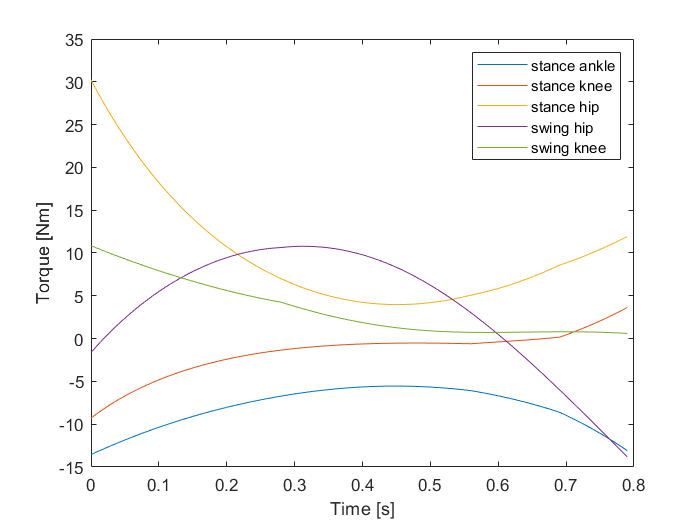

figure()
plot(time(1:end-1),T1_opt,...
     time(1:end-1),T2_opt,...
     time(1:end-1),T3_opt,...
     time(1:end-1),T4_opt,...
     time(1:end-1),T5_opt);
legend('stance ankle','stance knee','stance hip','swing hip','swing knee');
xlabel('Time [s]')
ylabel('Torque [Nm]')

Relative joint positions.

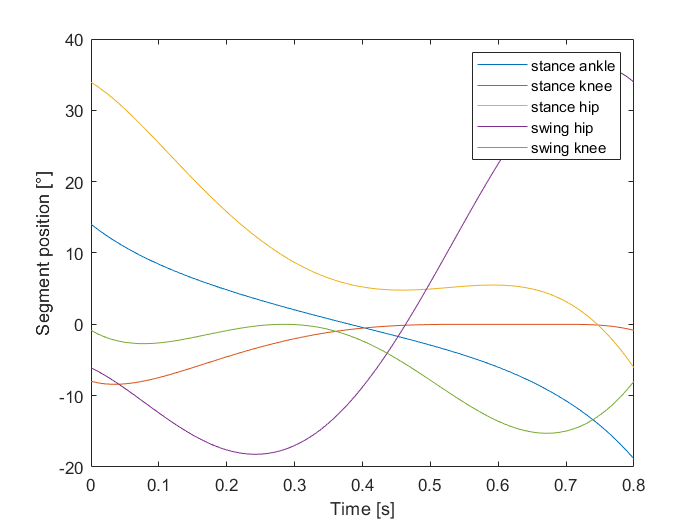

relJointPos = getRelativeJointPositions(...
    q1_opt,q2_opt,q3_opt,q4_opt,q5_opt);
figure()
plot(time,180/pi*relJointPos(1,:),...
     time,180/pi*relJointPos(2,:),...
     time,180/pi*relJointPos(3,:),...
     time,180/pi*relJointPos(4,:),...
     time,180/pi*relJointPos(5,:));
legend('stance ankle','stance knee','stance hip','swing hip','swing knee');
xlabel('Time [s]')
ylabel('Segment position [°]')

Relative joint velocities

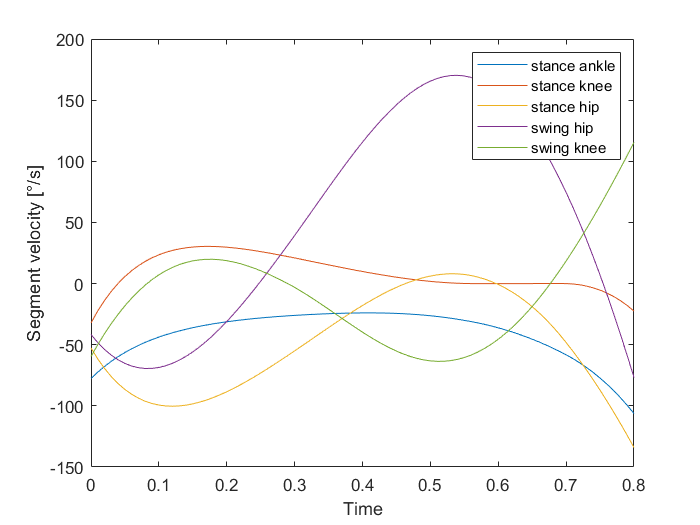

relJointVel = getRelativeJointVelocities(...
    dq1_opt,dq2_opt,dq3_opt,dq4_opt,dq5_opt);
figure()
plot(time,180/pi*relJointVel(1,:),...
     time,180/pi*relJointVel(2,:),...
     time,180/pi*relJointVel(3,:),...
     time,180/pi*relJointVel(4,:),...
     time,180/pi*relJointVel(5,:));
legend('stance ankle','stance knee','stance hip','swing hip','swing knee');
xlabel('Time')
ylabel('Segment velocity [°/s]')

### Maximum torque

max_torque=max(abs([T1_opt T2_opt T3_opt T4_opt T5_opt]));

disp(['The maximum torque is ', num2str(max_torque), ' Nm. Try to make it'...
      ' lower by playing with the weights.'])

The maximum torque is 30.2188 Nm. Try to make it lower by playing with the weights.



%Send Value to spreadsheet
name=input('What is your name?','s');
datainput{1}=name;
datainput{2}=max_torque;
datainput{3}=w1;
datainput{4}=w2;
datainput{5}=w3;
datainput{6}=w4;
datainput{7}=w5;
mat2sheets_v2('1LkQjvf8GK8CTqohY5sC50KnL9j36aRI2fBmuBAsj-Mw', '0', [1 1], datainput);  

### Generate an animation

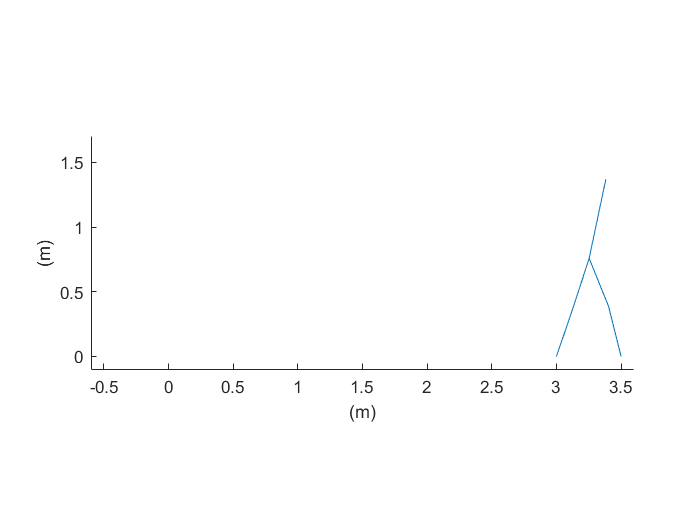

jointPositions_opt = getJointPositions(...
    l1,l2,l3,l4,l5,q1_opt,q2_opt,q3_opt,q4_opt,q5_opt)';
generateAnimation(jointPositions_opt, dt, strideLength);